Denoising Gaussian con Filtro Wiener

fullFileName = matlab.desktop.editor.getActiveFilename;
folderPath = fileparts(fullFileName);
folderPath = strrep(folderPath, 'MatLab', '');
folderPath = fullfile(folderPath, 'Python/dataset');
folderPath = fullfile(folderPath, 'original');
nome_img = 'Cat_August_2010-4.jpg';
folderPath = fullfile(folderPath, nome_img);

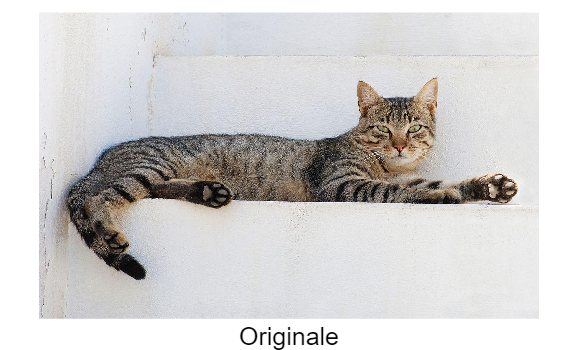

i2 = imread(folderPath);
imshow(i2)
text(size(i2,2)/2, size(i2,1) + 10, 'Originale', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 12);

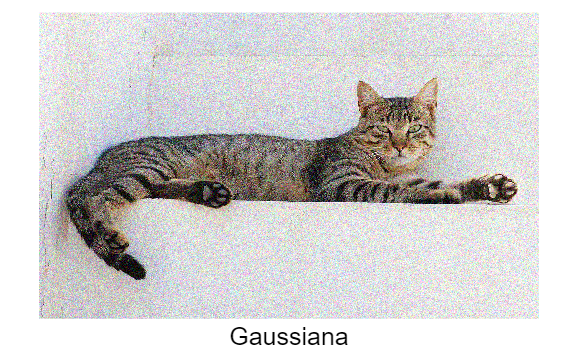

noisy_img = imnoise(i2, 'gaussian', 0, 0.01);
imshow(noisy_img)
text(size(i2,2)/2, size(i2,1) + 10, 'Gaussiana', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 12);

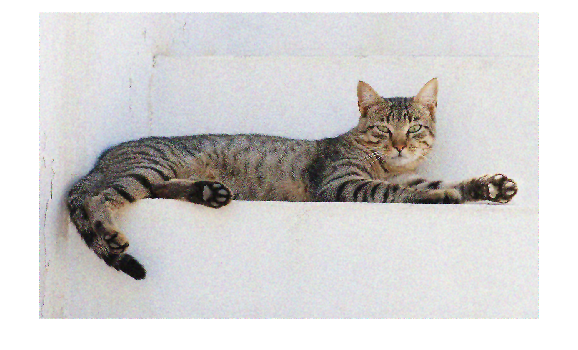

img_denoised = img_noisy;
for c = 1:3
    img_denoised(:,:,c) = wiener2(noisy_img(:,:,c), [5 5]);
end

imshow(img_denoised)



[peaksnr, snr] = psnr(i2, noisy_img)

peaksnr = 20.6879

snr = 18.6979


[peaksnr, snr] = psnr(i2, img_denoised)

peaksnr = 27.5441

snr = 25.4842

Il PSNR è aumentato quindi bene